addpath('time');

## Periodic motion propagation (e=0.7, a=46000km, Earth orbit)

Validation of the relative dynamics model on graphical check with the plots from *"Relative Dynamics and Control of Spacecraft Formation in Eccentic Orbit" *, G. Inalhan, M.Tillerson, J.P.How; 2002*.*

Initial conditions:

clear all
a=46000;
time_sim=2*pi*sqrt((a^3)/astroConstants(13))*4;
e=0.70;
n=sqrt(astroConstants(13)/(a^3));
teta_0=0;
dteta=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5);
init_conds=-[0 dteta*(((1+e)^0.5)*((1-e)^1.5))/((-n)*(2+e)) dteta 0];
init_conds_z=[0 1];

Run Simulink:

sim_out=sim('relative_dynamics.slx');

Plot

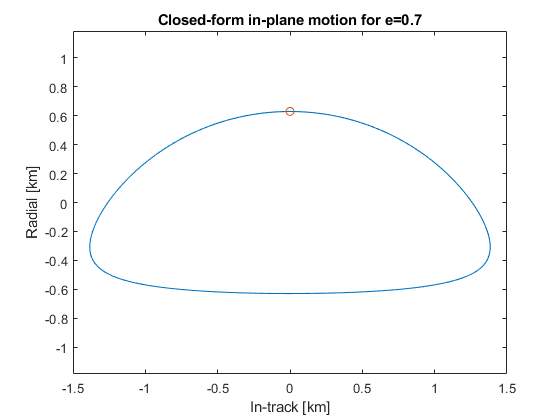

x=sim_out.simout.data(:,2);
y=sim_out.simout.data(:,4);
z=sim_out.z_z.data(:,2);

plot(y,x);
hold on
plot(y(1),x(1),'o')
axis equal
title('Closed-form in-plane motion for e=0.7')
xlabel('In-track [km]')
ylabel('Radial [km]')
xlim([-1.5 1.5])
hold off

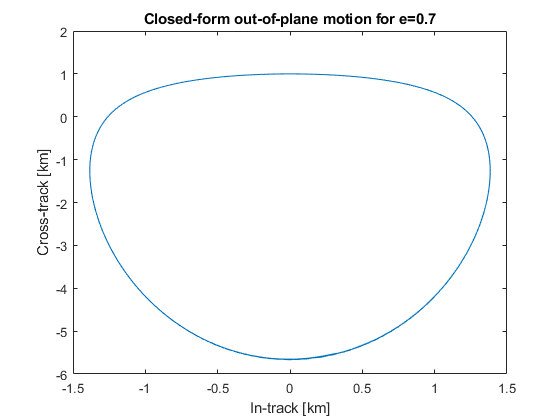

plot(y,z);
title('Closed-form out-of-plane motion for e=0.7')
xlabel('In-track [km]')
ylabel('Cross-track [km]')

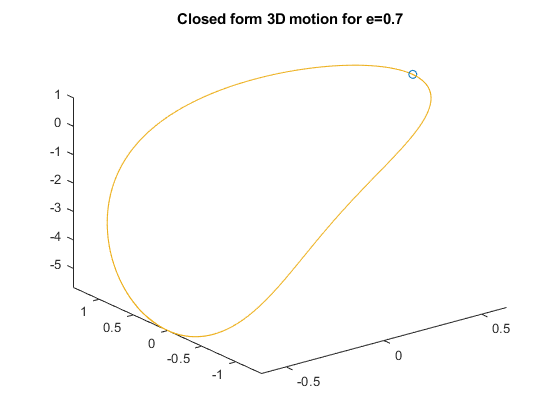

comet3(x,y,z)
title('Closed form 3D motion for e=0.7')

## Periodic motion propagation (Asteroid)

clear all
a=1.4*astroConstants(2);
time_sim=2*pi*sqrt((a^3)/astroConstants(4));
e=0.5;
n=sqrt(astroConstants(4)/(a^3));
teta_0=0;
k= 100;%-83.33333 %to change the size of the regular orbit
dteta_k=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
init_conds=[0 dteta_k*(((1+e)^0.5)*((1-e)^1.5))/((-n)*(2+e)) dteta_k 0];
init_conds_z=[0 1];

Run Simulink:

sim_out_SK=sim('relative_dynamics.slx');

Plot

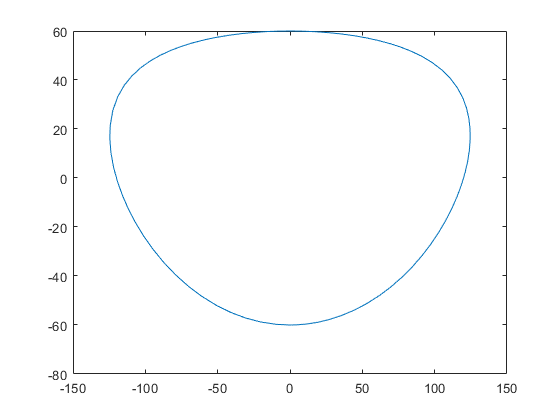

x=sim_out_SK.simout.data(:,2);
y=sim_out_SK.simout.data(:,4);
z=sim_out_SK.z_z.data(:,2);
plot(y,x);

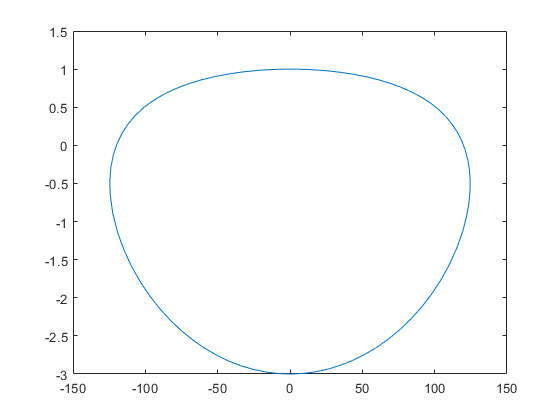

plot(y,z)

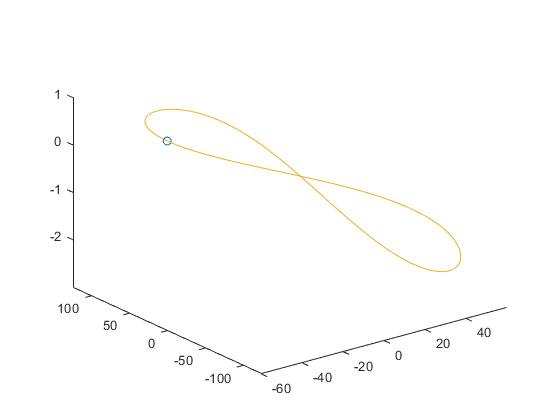

comet3(x,y,z)

## Station keeping (20km,0km) (Asteroid)

clear all
a=1.4*astroConstants(2);
time_sim=3600;%2*pi*sqrt((a^3)/astroConstants(4));
e=0.5;
n=sqrt(astroConstants(4)/(a^3));
teta_0=deg2rad(180);
k= 100;%-83.33333 %to change the size of the regular orbit
dteta_k=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
reference_conds=[-20,0];
init_conds=[0 -20 0 0];

Run Simulink:

sim_out_DC_SK=sim('relative_DC_SK.slx');

Plot

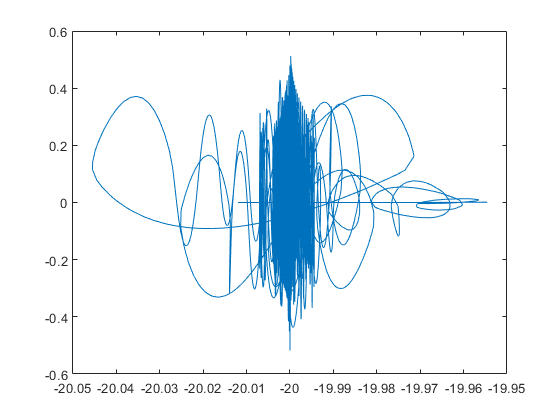

x=sim_out_DC_SK.simout.data(:,2);
y=sim_out_DC_SK.simout.data(:,4);
plot(x,y);

## Infinite Horizon Control (LQR)

clear all
a=1.4*astroConstants(2);
time_sim=3600;%2*pi*sqrt((a^3)/astroConstants(4));
e=0.5;
n=sqrt(astroConstants(4)/(a^3));
teta_0=deg2rad(180);
k= 100;%-83.33333 %to change the size of the regular orbit
dteta=(n*(1+e*cos(teta_0))^2)/((1-e^2)^1.5)*k;
reference_conds=[-21,0];
init_conds=[0 -20 0 0];
init_conds_z=[0 0];

T=[dteta^2 dteta*(-(n*2*(1+e*cos(teta_0))*e*sin(teta_0)/((1-e^2)^1.5))) 0 0; 0 dteta 0 0; 0 0 dteta^2 dteta*(-(n*2*(1+e*cos(teta_0))*e*sin(teta_0)/((1-e^2)^1.5))); 0 0 0 dteta];
true_anom=teta_0;
A_ss=[ 2*e*sin(true_anom)/(1+e*cos(true_anom)), (3+e*cos(true_anom))/(1+e*cos(true_anom)), 2, -2*e*sin(true_anom)/(1+e*cos(true_anom)); 
    1, 0, 0, 0;
   -2, 2*e*sin(true_anom)/(1+e*cos(true_anom)), 2*e*sin(true_anom)/(1+e*cos(true_anom)), e*cos(true_anom)/(1+e*cos(true_anom));
   0, 0, 1, 0];
B_ss=((1-(e^2))^3)/(((1+e*cos(true_anom))^4)*(n^2))*[1 0; 0 0; 0 1; 0 0];
T_inv=[1/dteta 0 0 0; 0 1 0 0; 0 0 1/dteta 0; 0 0 0 1];
C=[0 1 0 0; 0 0 0 1]; %VELOCITY CHANGED
A=T*A_ss*T_inv;
B=T*B_ss;
Wzz=eye(2);
Q=C'*Wzz*C;
R=10000000*eye(2);
K=lqr(A,B,Q,R);

M=-inv(C*inv(A-B*K)*B)

M = 	1.0e+-3 *

    0.3162   -0.0000
    0.0000    0.3162


Run Simulink:

sim_out_HC=sim('relative_dynamics_Horizon_Control.slx');

Plotting the results:

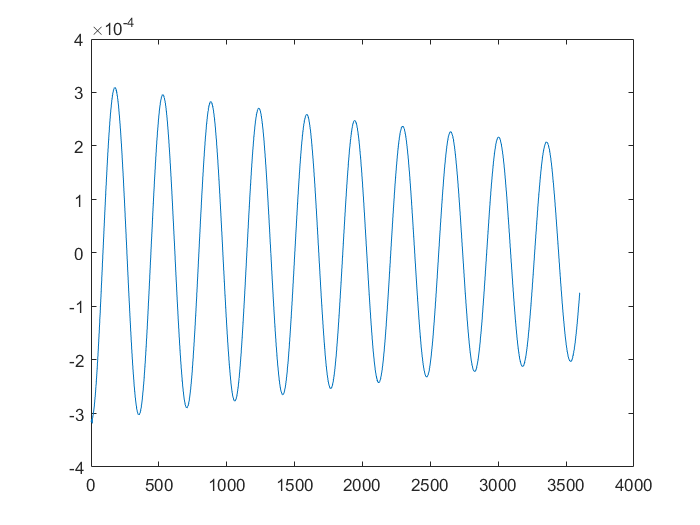

plot(sim_out_HC.thrust.time, sim_out_HC.thrust.data(:,1))

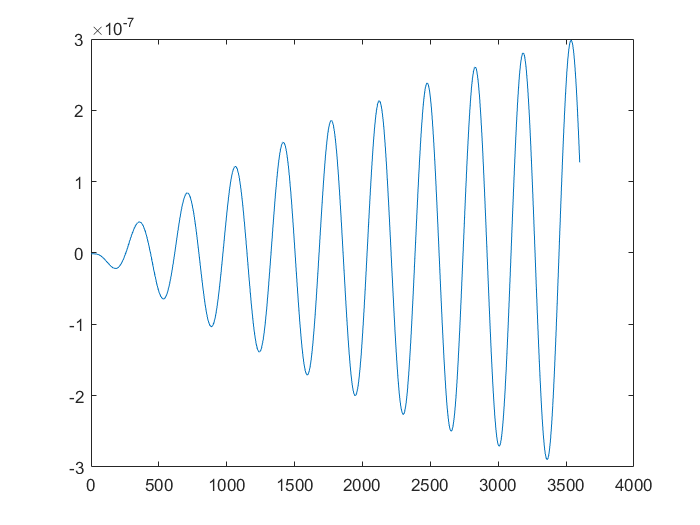

plot(sim_out_HC.thrust.time, sim_out_HC.thrust.data(:,2))